# Scale Image To Fit Page

This example shows, for PDF and Word reports, how to scale a large image to fit on a page.

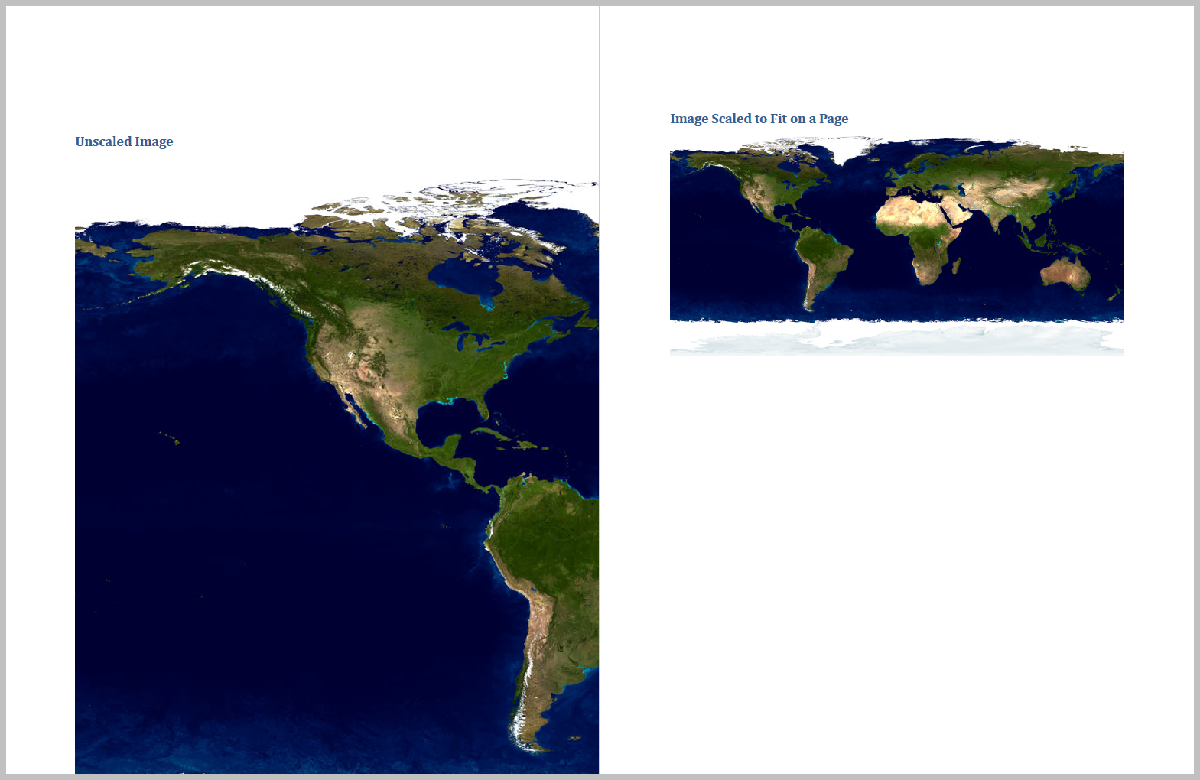

Import the DOM and Report API packages so you do not have to use long, fully-qualified class names.

import mlreportgen.dom.*
import mlreportgen.report.*

Create and open a report.

% To create a Word report, change the output type from "pdf" to "docx". 
rpt = Report("myreport","pdf");
open(rpt);

Specify an image that is too large to fit on the page.

imgPath = which("landOcean.jpg");

Add a heading to the report.

heading = Heading1("Unscaled Image");
add(rpt,heading);

Add the image to the report using the DOM *Image* class.

img1 = Image(imgPath);
add(rpt,img1);

Add a heading to the report.

heading = Heading1("Image Scaled to Fit on a Page");
add(rpt,heading);

Use the DOM *ScaleToFit* format to scale the image to fit on the page and then, add the scaled image to the report.

img2 = Image(imgPath);
img2.Style = [img2.Style {ScaleToFit}];
add(rpt,img2);

Close and view the report.

close(rpt);
rptview(rpt);

*Copyright 2018 The MathWorks, Inc.*